# Movie Rating and Box Office Analysis

## Reads .CSV File onto MATLAB

actors_data = readtable('TrainingData.csv');
actors_matrix = table2cell(actors_data);

[rows, cols] = size(actors_data);

new_certification = zeros(rows,1);
new_genres = strings(rows,3);

## Preprocessing data for Age Rating

for i=1:rows
    if actors_matrix(i,3) == "G"
        new_certification(i,1) = 100;
        
    elseif actors_matrix(i,3) == "PG"
        new_certification(i,1) = 250;
        
    elseif actors_matrix(i,3) == "PG13"
        new_certification(i,1) = 500;
        
    elseif actors_matrix(i,3) == "R"
        new_certification(i,1) = 1000;
        
    elseif actors_matrix(i,3) == "NC-17"
        new_certification(i,1) = 750;
        
    elseif actors_matrix(i,3) == "Not Rated"
        new_certification(i,1) = 50;
        
    elseif actors_matrix(i,3) == "None"
        new_certification(i,1) = 0;
    end
end
new_certification = num2cell(new_certification);

actors_matrix(:,3) = new_certification;



## Preprocessing data for genres

k = 27;

for i=1:3
    for j=1:rows
        if actors_matrix(j,k) == ""
            new_genres(j,i) = "";
            
        elseif actors_matrix(j,k) == "Action"
            new_genres(j,i) = "Action-Adventure";
        
        elseif actors_matrix(j,k) == "Adventure"
            new_genres(j,i) = "Action-Adventure";
            
        elseif actors_matrix(j,k) == "Animation"
            new_genres(j,i) = "Fantasy-Animation-Short";
            
        elseif actors_matrix(j,k) == "Biography"
            new_genres(j,i) = "Biography";
            
        elseif actors_matrix(j,k) == "Comedy"
            new_genres(j,i) = "Comedy-Romance";
            
        elseif actors_matrix(j,k) == "Crime"
            new_genres(j,i) = "Drama-Thriller";
         
        elseif actors_matrix(j,k) == "Documentary"
            new_genres(j,i) = "Biography";
        
        elseif actors_matrix(j,k) == "Drama"
            new_genres(j,i) = "Drama-Thriller";
            
        elseif actors_matrix(j,k) == "Family"
            new_genres(j,i) = "Comedy-Romance";
            
        elseif actors_matrix(j,k) == "Fantasy"
            new_genres(j,i) = "Fantasy-Animation-Short";
            
        elseif actors_matrix(j,k) == "Film Noir"
            new_genres(j,i) = "Biography";
            
        elseif actors_matrix(j,k) == "History"
            new_genres(j,i) = "Biography";
            
        elseif actors_matrix(j,k) == "Horror"
            new_genres(j,i) = "Drama-Thriller";
            
        elseif actors_matrix(j,k) == "Music"
            new_genres(j,i) = "Comedy-Romance";
            
        elseif actors_matrix(j,k) == "Musical"
            new_genres(j,i) = "Comedy-Romance";
            
        elseif actors_matrix(j,k) == "Mystery"
            new_genres(j,i) = "Drama-Thriller";
            
        elseif actors_matrix(j,k) == "Romance"
            new_genres(j,i) = "Comedy-Romance";
            
        elseif actors_matrix(j,k) == "Sci-Fi"
            new_genres(j,i) = "Fantasy-Animation-Short";
            
        elseif actors_matrix(j,k) == "Short Film"
            new_genres(j,i) = "Fantasy-Animation-Short";
            
        elseif actors_matrix(j,k) == "Sport"
            new_genres(j,i) = "Biography";
            
        elseif actors_matrix(j,k) == "Superhero"
            new_genres(j,i) = "Action-Adventure";
            
        elseif actors_matrix(j,k) == "Thriller"
            new_genres(j,i) = "Drama-Thriller";
            
        elseif actors_matrix(j,k) == "War"
            new_genres(j,i) = "Action-Adventure";
            
        elseif actors_matrix(j,k) == "Western"
            new_genres(j,i) = "Action-Adventure";
        end
    end
    k = k + 1;
end

new_genres = cellstr(new_genres);
actors_matrix(:,27:29) = new_genres;


## Convert table into cell

new_col = 0;
k = 27;
for i=1:3
    for j=1:rows
        if actors_matrix(j,k) ~= ""
            new_col = new_col + 1;
        end
    end
    k = k + 1;
end

all_genres_matrix = cell(new_col,27);

## Reorganized Genres

index=1;
for i=1:rows
    if actors_matrix(i,27) ~= ""
        all_genres_matrix(index,:) = actors_matrix(i,1:27);
        index = index + 1;
    end
end

for i=1:rows
    if actors_matrix(i,28) ~= ""
        all_genres_matrix(index,:) = actors_matrix(i,[1:26 28]);
        index = index + 1;
    end
end

for i=1:rows
    if actors_matrix(i,29) ~= ""
        all_genres_matrix(index,:) = actors_matrix(i,[1:26 29]);
        index = index + 1;
    end
end

sorted_genres = sortrows(all_genres_matrix, 27);
[id , genres] = findgroups(sorted_genres(:,27));
id = num2cell(id);
sorted_genres(:,28) = id;
genre_list = sorted_genres(:,27);
[rows, cols] = size(sorted_genres);

## Histogram Of Year

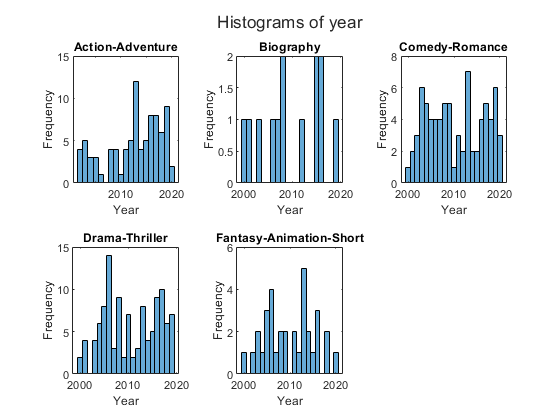

num_of_genres = length(genres);
tiled_col = num_of_genres / 3;
tiled_col = ceil(tiled_col);
figure('Name','Histograms of year')
t = tiledlayout(tiled_col,3);
title(t, 'Histograms of year')

for i=1:num_of_genres
    nexttile;
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    year = genre_row(:,2);
    year = cell2mat(year);
    histogram(year)
    title(genres(i,1))
    xlabel('Year')
    ylabel('Frequency')
end

## Histogram Of IMDb Rating

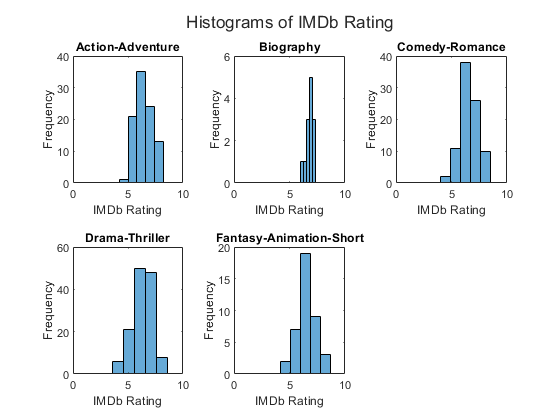

figure('Name','Histograms of IMDb Rating')
t = tiledlayout(tiled_col,3);
title(t, 'Histograms of IMDb Rating')

for i=1:num_of_genres
    nexttile;
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    imdb_rating = genre_row(:,6);
    imdb_rating = cell2mat(imdb_rating);
    histogram(imdb_rating,5)
    title(genres(i,1))
    xlim([0, 10]);
    xlabel('IMDb Rating')
    ylabel('Frequency')
end

## Histogram of MetaScore

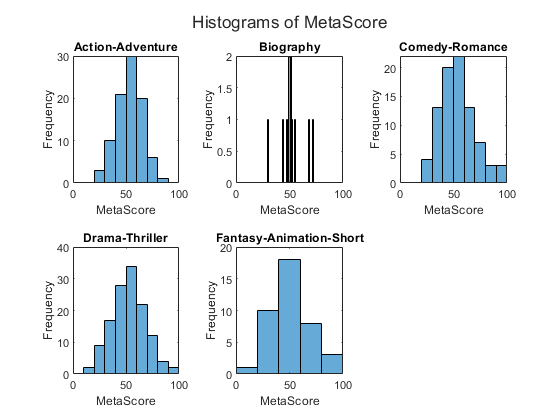

figure('Name','Histograms of MetaScore')
t = tiledlayout(tiled_col,3);
title(t, 'Histograms of MetaScore')

for i=1:num_of_genres
    nexttile;
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    metaScore = genre_row(:,7);
    metaScore = cell2mat(metaScore);
    histogram(metaScore)
    title(genres(i,1))
    xlim([0, 100]);
    xlabel('MetaScore')
    ylabel('Frequency')
end

## Histogram of WorldWide Revenue

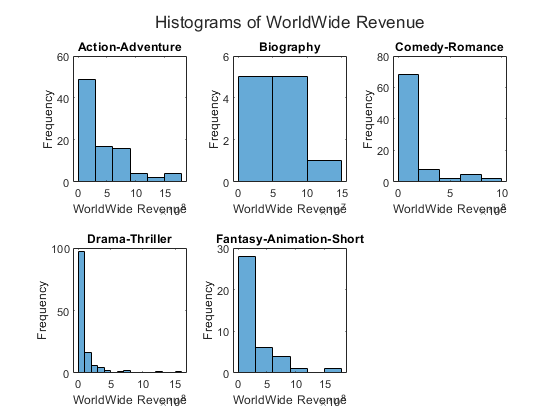

figure('Name','Histograms of WorldWide Revenue')
t = tiledlayout(tiled_col,3);
title(t, 'Histograms of WorldWide Revenue')

for i=1:num_of_genres
    nexttile;
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    worldWide = genre_row(:,26);
    worldWide = cell2mat(worldWide);
    histogram(worldWide)
    title(genres(i,1))
    xlabel('WorldWide Revenue')
    ylabel('Frequency')
end

## Normal Distribtion

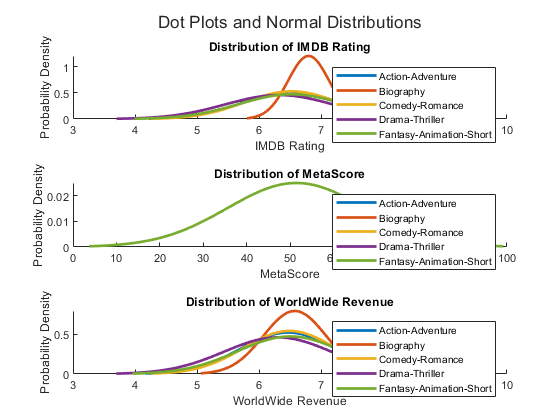

figure('Name',"Dot Plots and Normal Distributions")
t = tiledlayout(3,1);
title(t,"Dot Plots and Normal Distributions");

nexttile;
hold on
for i=1:num_of_genres
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    imdB_rating = genre_row(:,6);
    imdB_rating = cell2mat(imdB_rating);
    %scatter(imdB_rating,ones(size(imdB_rating)));
    [Mu, Sigma] = normfit(imdB_rating);
    x = linspace(Mu-3*Sigma,Mu+3*Sigma,100);
    plot(x,normpdf(x,Mu,Sigma),'LineWidth', 2);
end
legend(genres)
xlabel("IMDB Rating");
ylabel("Probability Density");
title('Distribution of IMDB Rating');
hold off

nexttile;
hold on
for i=1:num_of_genres
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    metaScore = genre_row(:,7);
    metaScore = cell2mat(metaScore);
    %scatter(metaScore,ones(size(metaScore)));
    [Mu2, Sigma2] = normfit(metaScore);
    x2 = linspace(Mu2-3*Sigma2,Mu2+3*Sigma2,100);
    plot(x2,normpdf(x2,Mu2,Sigma2),'LineWidth', 2);
end
legend(genres)
xlabel("MetaScore");
ylabel("Probability Density");
title('Distribution of MetaScore');
hold off

nexttile;
hold on
for i=1:num_of_genres
    genre_row = cell(rows, cols);
    for j=1:rows
        if isequal(sorted_genres{j,28},i)
            genre_row(j,:) = sorted_genres(j,:);
        end
    end
    worldWide = genre_row(:,12);
    worldWide = cell2mat(worldWide);
    %scatter(worldWide,ones(size(worldWide)));
    [Mu3, Sigma3] = normfit(worldWide);
    x3 = linspace(Mu3-3*Sigma3,Mu3+3*Sigma3,100);
    plot(x3,normpdf(x3,Mu3,Sigma3),'LineWidth', 2);
end
legend(genres)
xlabel("WorldWide Revenue");
ylabel("Probability Density");
title('Distribution of WorldWide Revenue');
hold off

## 2D Scatter Plot

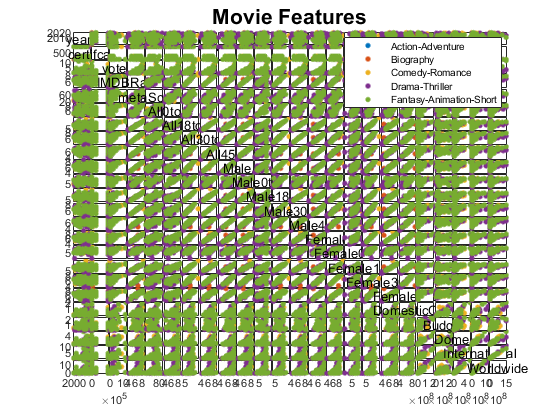

features = {' years ',' certifcation ' ,' votes ' ,' IMDBRatings ' ,' metaScores ' ,' All0to17 ' ,' All18to29 ' ,' All30to44 ' ,' All45to ' ,' MaleAll ' ,' Male0to17 ' ,' Male18to29 ' ,' Male30to44 ' ,' Male45to ' ,' FemaleAll ' ,' Female0to17 ' ,' Female18to29 ' ,' Female30to44 ' ,' Female45to ' ,' DomesticOpening ' ,' Budget ' ,' Domestic ' ,' International ' ,' Worldwide '};
colors = lines(5);
scatter_X = cell2mat(sorted_genres(:,[2:4 6:26]));
figure('Name','Movie Features')
hold on
gplotmatrix(scatter_X,[],sorted_genres(:,27),colors,'.',12,[],'variable',features);
title({'Movie Features','Scatter Plot Matrix'},'FontSize',16)
hold off

## **Preprocessing: Center and scale**

data = cell2mat(sorted_genres(:,[2:4 6:26]));
means = nanmean(data);
vars = nanvar(data);
stdevs = nanstd(data);
[nrows, ncols] = size(data);
X = zeros([nrows,ncols]);

% Mean center data 
for i=1:ncols 
    for j=1:nrows 
        X(j,i) = -(means(:,i) - data(j,i)); 
    end 
end 
mean(X)

ans = 	1.0e+-9 *

       NaN   -0.0002   -0.1516   -0.0000       NaN       NaN    0.0000    0.0000       NaN   -0.0000       NaN   -0.0000    0.0000       NaN   -0.0000       NaN    0.0000   -0.0000       NaN       NaN       NaN       NaN       NaN       NaN


nanmean(X)

ans = 	1.0e+-6 *

    0.0000   -0.0000   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0284   -0.0047   -0.0433   -0.0048    0.1743



% Scale data
for i=1:ncols 
    for j=1:nrows 
        X(j,i) = X(j,i) / stdevs(:,i); 
    end 
end         

var(X)

ans =        NaN    1.0000    1.0000    1.0000       NaN       NaN    1.0000    1.0000       NaN    1.0000       NaN    1.0000    1.0000       NaN    1.0000       NaN    1.0000    1.0000       NaN       NaN       NaN       NaN       NaN       NaN


nanvar(X)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


## **SVD**

data = cell2mat(sorted_genres(:,[2:4 6:26 28]));
data(isnan(data)) = 0;
data(isinf(data)) = 0;
X(isnan(X)) = 0;
X(isinf(X)) = 0;
% X is the original dataset 
% Ur will be the transformed dataset  
% S is covariance matrix (not normalized) 
%
labels = data(:,25);
[U S V] = svd(X,0);
U(:,1) = labels;
%Randomize U and attach the region label
U = U(randperm(size(U, 1)),:);
randomizedULabels = U(:,1);
U(:,1) = randomizedULabels;

%Makes the randomize U become Ur and then label as r
Ur = U*S;
Ur(:,1) = randomizedULabels;

## Scree Plots

Obtain the necessary information for Scree Plots Obtain S^2 (and can also use to normalize S) 

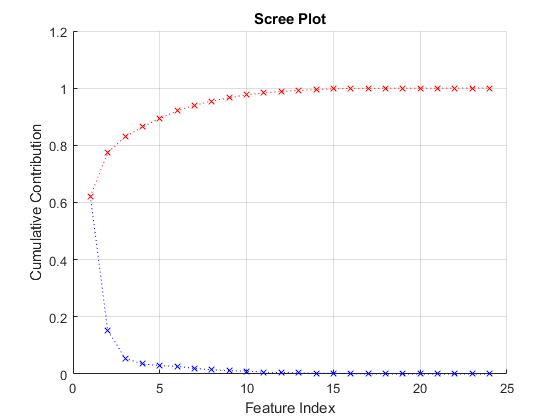

nfeatures = 24;
S2 = S^2; 
weights2 = zeros(nfeatures,1);
sumS2 = sum(sum(S2)); 
weightsum2 = 0; 

for i=1:nfeatures 
    weights2(i) = S2(i,i)/sumS2; 
    weightsum2 = weightsum2 + weights2(i); 
    weight_c2(i) = weightsum2; 
end

% plot
figure('Name','Scree Plot')
hold on
plot(weights2,'x:b'); 
plot(weight_c2,'x:r'); 
grid; 
title('Scree Plot'); 
xlabel('Feature Index');
ylabel('Cumulative Contribution');
hold off

## Loading Vectors

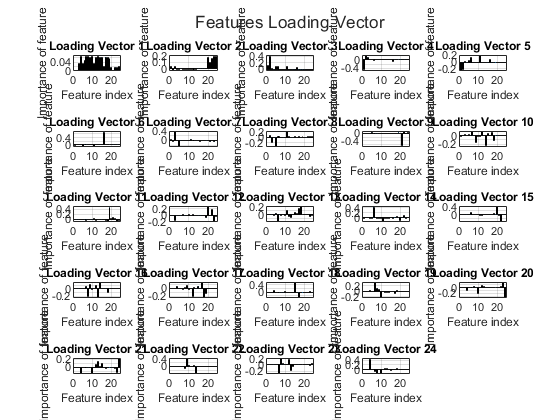

for i=1:nfeatures 
    for j=1:nfeatures 
        Vsquare(i,j) = V(i,j)^2; 
        if V(i,j)<0 
            Vsquare(i,j) = Vsquare(i,j)*-1; 
        else  
            Vsquare(i,j) = Vsquare(i,j)*1; 
        end 
    end 
end

% plot
figure('Name','Loading Vectors')
t = tiledlayout(5,5);
title(t,'Features Loading Vector');
for i=1:nfeatures
    nexttile;
    bar(Vsquare(:,i),0.5);
    grid;
    ymin = min(Vsquare(:,i)) + (min(Vsquare(:,i))/10);
    ymax = max(Vsquare(:,i)) + (max(Vsquare(:,i))/10);
    axis([0 25 ymin ymax]);
    xlabel('Feature index');
    ylabel('Importance of feature');
    [chart_title, ERRMSG] = sprintf('Loading Vector %d',i);
    title(chart_title);
end

## 3D PCA

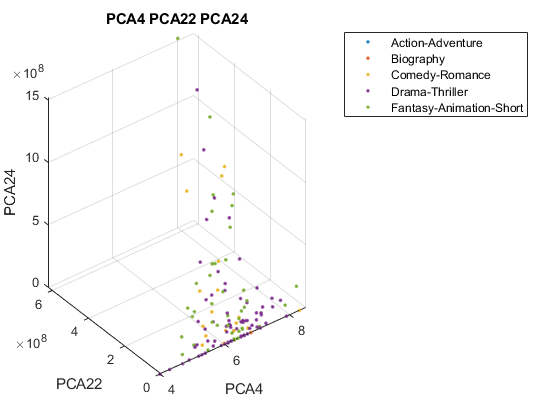

figure('Name',"PCA4 PCA22 PCA24")
idx1 = 1;
idx2 = 0;
grid on
for i=1:rows
    if data(i,25) == 1
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,4),data(idx1:idx2,22), data(idx1:idx2,24),'.');

hold on;
idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 2
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,4),data(idx1:idx2,22), data(idx1:idx2,24),'.');

idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 3
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,4),data(idx1:idx2,22), data(idx1:idx2,24),'.');

idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 4
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,4),data(idx1:idx2,22), data(idx1:idx2,24),'.');

idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 5
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,4),data(idx1:idx2,22), data(idx1:idx2,24),'.');
title("PCA4 PCA22 PCA24")
legend(genres)
xlabel("PCA4")
ylabel("PCA22")
zlabel("PCA24")
hold off;

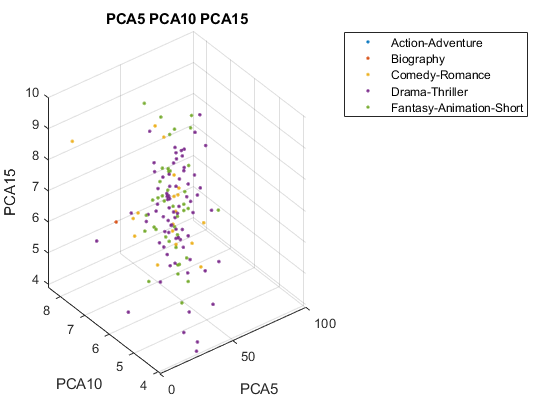


figure('Name',"PCA5 PCA10 PCA15")
idx1 = 1;
idx2 = 0;
grid on
for i=1:rows
    if data(i,25) == 1
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,5),data(idx1:idx2,10), data(idx1:idx2,15),'.');

hold on;
idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 2
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,5),data(idx1:idx2,10), data(idx1:idx2,15),'.');

idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 3
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,5),data(idx1:idx2,10), data(idx1:idx2,15),'.');

idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 4
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,5),data(idx1:idx2,10), data(idx1:idx2,15),'.');

idx1 = idx2 + 1;
for i=1:rows
    if data(i,25) == 5
        idx2 = idx2 + 1;
    end
end
scatter3(data(idx1:idx2,5),data(idx1:idx2,10), data(idx1:idx2,15),'.');
title("PCA5 PCA10 PCA15")
legend(genres)
xlabel("PCA5")
ylabel("PCA10")
zlabel("PCA15")
hold off;

yfit = trainedModel.predictFcn(3)

Unable to resolve the name trainedModel.predictFcn.

function [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% Returns a trained classifier and its accuracy. This code recreates the
% classification model trained in Classification Learner app. Use the
% generated code to automate training the same model with new data, or to
% learn how to programmatically train models.
%
%  Input:
%      trainingData: A matrix with the same number of columns and data type
%       as the matrix imported into the app.
%
%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy in percent. In
%       the app, the History list displays this overall accuracy score for
%       each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a matrix containing only the predictor columns used for
% training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 26-May-2021 20:06:47


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table

inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24', 'column_25'});

predictorNames = {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24'};
predictors = inputTable(:, predictorNames);
response = inputTable.column_25;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'deviance', ...
    'MaxNumSplits', 3, ...
    'Surrogate', 'off', ...
    'ClassNames', [1; 2; 3; 4; 5]);

% Create the result struct with predict function
predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
trainedClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.ClassificationTree = classificationTree;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2020a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 24 columns because this model was trained using 24 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24', 'column_25'});

predictorNames = {'column_1', 'column_2', 'column_3', 'column_4', 'column_5', 'column_6', 'column_7', 'column_8', 'column_9', 'column_10', 'column_11', 'column_12', 'column_13', 'column_14', 'column_15', 'column_16', 'column_17', 'column_18', 'column_19', 'column_20', 'column_21', 'column_22', 'column_23', 'column_24'};
predictors = inputTable(:, predictorNames);
response = inputTable.column_25;
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end